A = [0, 1; -2400, -100]

A =            0           1
       -2400        -100


B = [0; 9]

B =      0
     9


C = [600, 0]

C =    600     0


D = 0

D = 0

Sistema

sys = ss(A, B, C, D)


sys =
 
  A = 
          x1     x2
   x1      0      1
   x2  -2400   -100
 
  B = 
       u1
   x1   0
   x2   9
 
  C = 
        x1   x2
   y1  600    0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Verifico che la coppia A C sia osservabile

OB = obsv(A, C)

OB =    600     0
     0   600


rank(OB)

ans = 2

Assegno al sistema gli autovalori che disidero (-120 e -180)

eig(A)

ans =    -40
   -60


new_eig = [-120, -180]

new_eig =   -120  -180


L = place(A', C', new_eig)'     % nota le trasposizioni

L =     0.3333
   -1.3333


A_ = A-L*C

A_ = 	1.0e+03 *

   -0.2000    0.0010
   -1.6000   -0.1000


eig(A_)

ans =  -180.0000
 -120.0000


Sistema dell'osservatore

sys_ob = ss(A_, B, C, D)


sys_ob =
 
  A = 
          x1     x2
   x1   -200      1
   x2  -1600   -100
 
  B = 
       u1
   x1   0
   x2   9
 
  C = 
        x1   x2
   y1  600    0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Risposta sistema retroazionato ad ingresso a onda quadra 0.5Hz, ampiezza 2

t = 0:0.01:10;
r = 2*sign(sin(2*pi*0.5*t));

x_0 1

x_0 = [0; 0]

x_0 =      0
     0


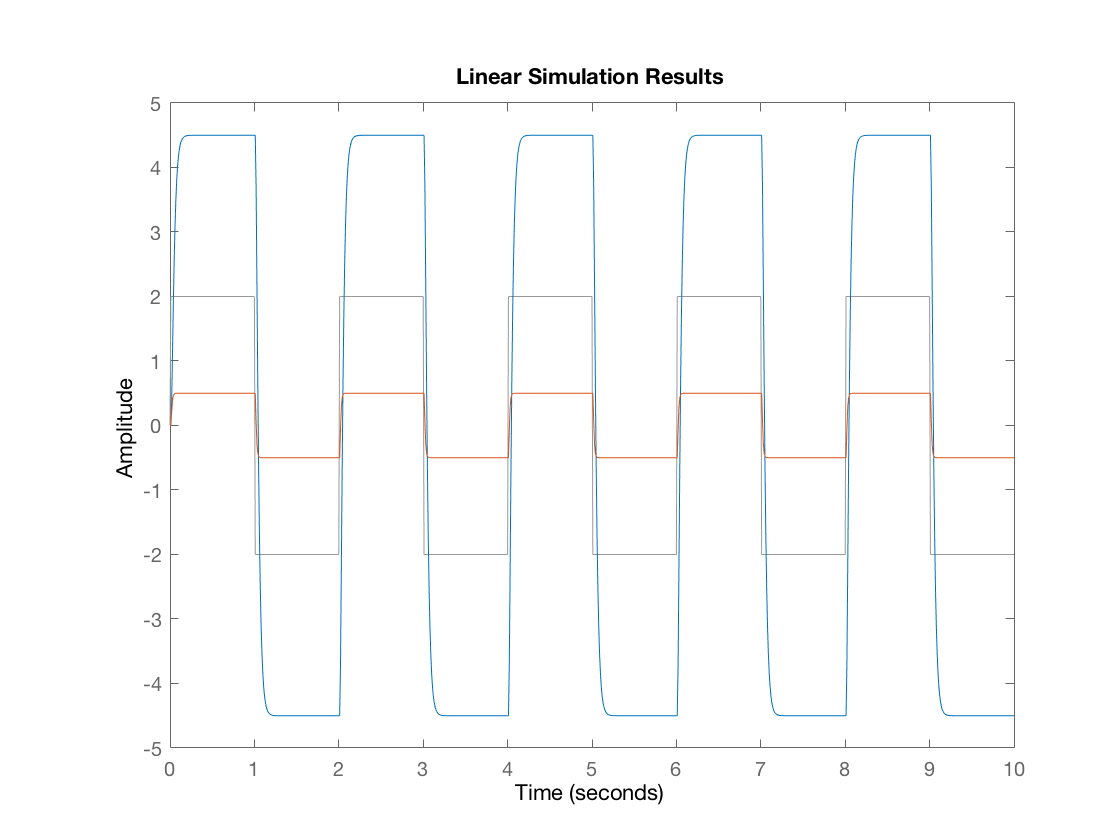

lsim(sys, sys_ob, r, t, x_0)

x_0 2

x_0 = [0.01; 0]

x_0 =     0.0100
         0


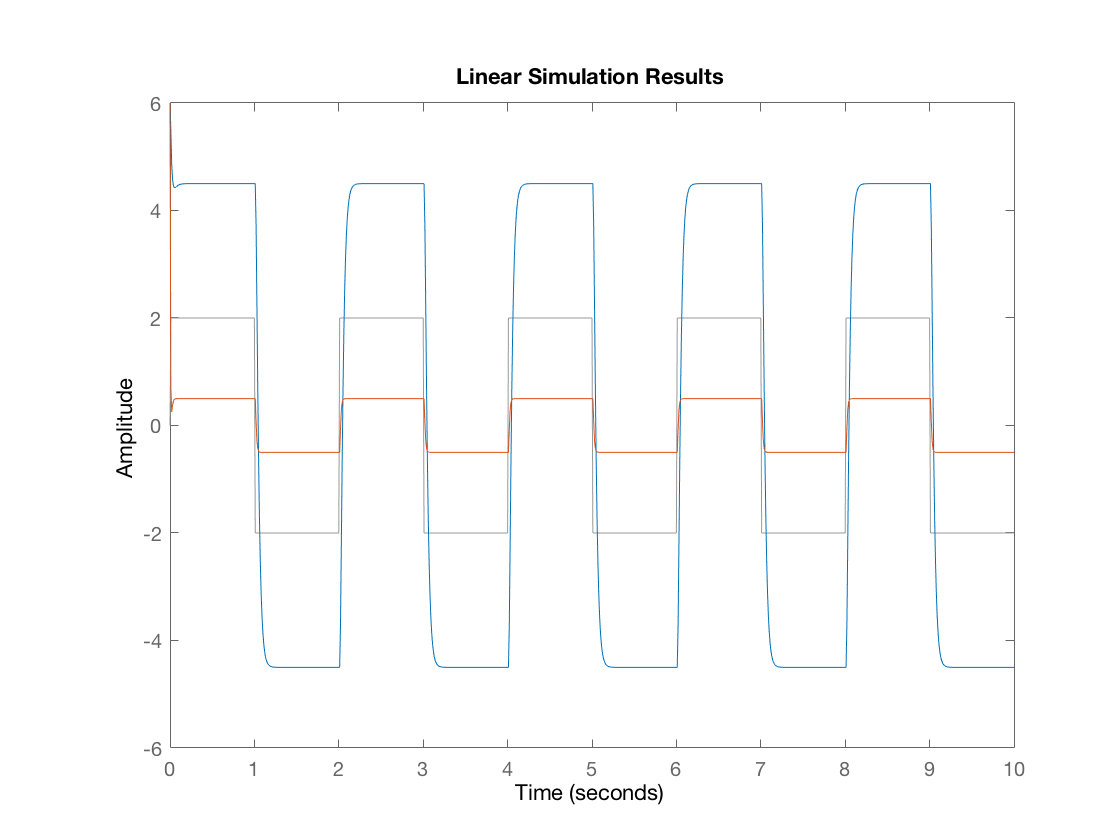

lsim(sys, sys_ob, r, t, x_0)

x_0 3

x_0 = [-0.01; 0]

x_0 =    -0.0100
         0


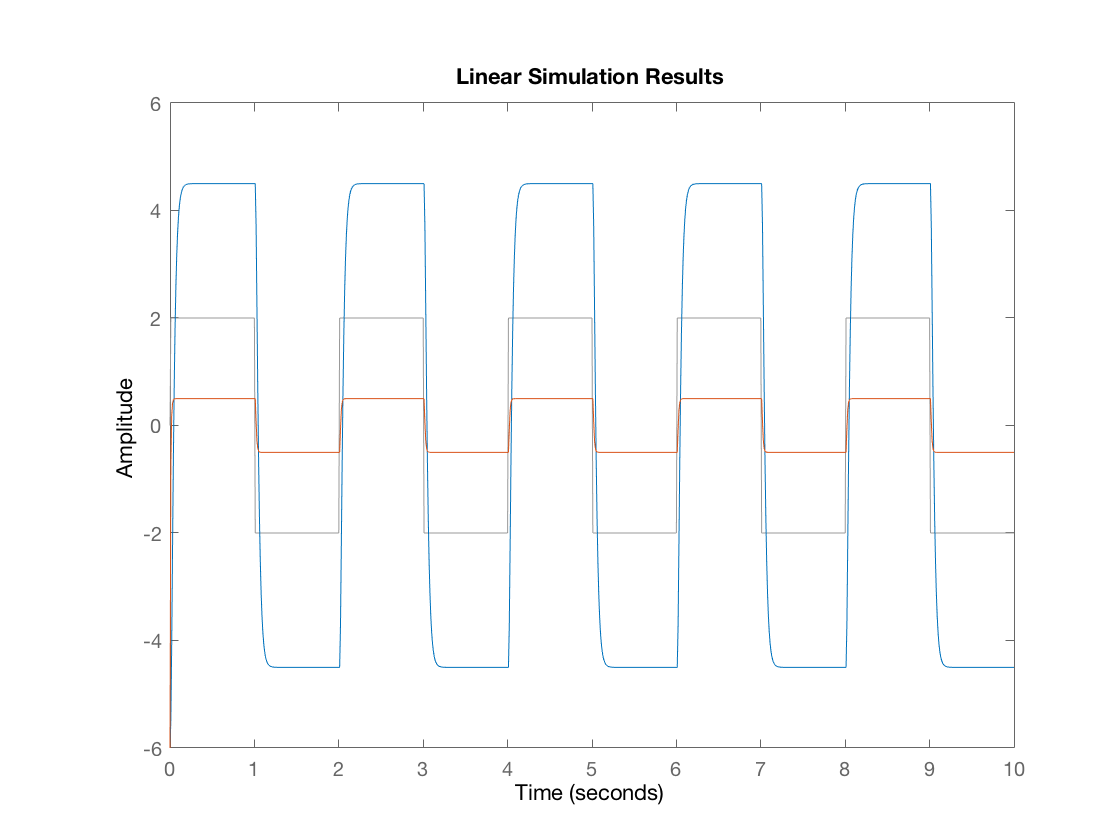

lsim(sys, sys_ob, r, t, x_0)